# Neurodata Without Borders Extracellular Electrophysiology Tutorial

## About This Tutorial

This tutorial describes storage of hypothetical data from extracellular electrophysiology experiments in NWB for the following data categories:

- Raw voltage recording

- Local field potential (LFP) and filtered electrical signals

- Spike times

## Before You Begin

It is recommended to first work through the [Introduction to MatNWB tutorial](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/intro.html), which demonstrates installing MatNWB and creating an NWB file with subject information, animal position, and trials, as well as writing and reading NWB files in MATLAB.

**Important**: The dimensions of timeseries data in MatNWB should be defined in the opposite order of how it is defined in the nwb-schemas. In NWB, time is always stored in the first dimension of the data, whereas in MatNWB time should be stored in the last dimension of the data. This is explained in more detail here: [MatNWB <-> HDF5 Dimension Mapping](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/dimensionMapNoDataPipes.html).

## Setting up the NWB File

An NWB file represents a single session of an experiment. Each file must have a `session_description`, `identifier`, and `session_start_time`. Create a new [`NWBFile`](https://neurodatawithoutborders.github.io/matnwb/doc/NwbFile.html) object these required fields along with any additional metadata. In MatNWB, arguments are specified using MATLAB's keyword argument pair convention, where each argument name is followed by its value.

nwb = NwbFile( ...
    'session_description', 'mouse in open exploration',...
    'identifier', 'Mouse5_Day3', ...
    'session_start_time', datetime(2018, 4, 25, 2, 30, 3, 'TimeZone', 'local'), ...
    'timestamps_reference_time', datetime(2018, 4, 25, 3, 0, 45, 'TimeZone', 'local'), ...
    'general_experimenter', 'Last Name, First Name', ... % optional
    'general_session_id', 'session_1234', ... % optional
    'general_institution', 'University of My Institution', ... % optional
    'general_related_publications', {'DOI:10.1016/j.neuron.2016.12.011'}); % optional
nwb

## Electrode Information

In order to store extracellular electrophysiology data, you first must create an electrodes table describing the electrodes that generated this data. Extracellular electrodes are stored in an `electrodes` table, which is also a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html). `electrodes` has several required fields: `x`, `y`, `z`, `impedance`, `location`, `filtering`, and `electrode_group`.

### Electrodes Table

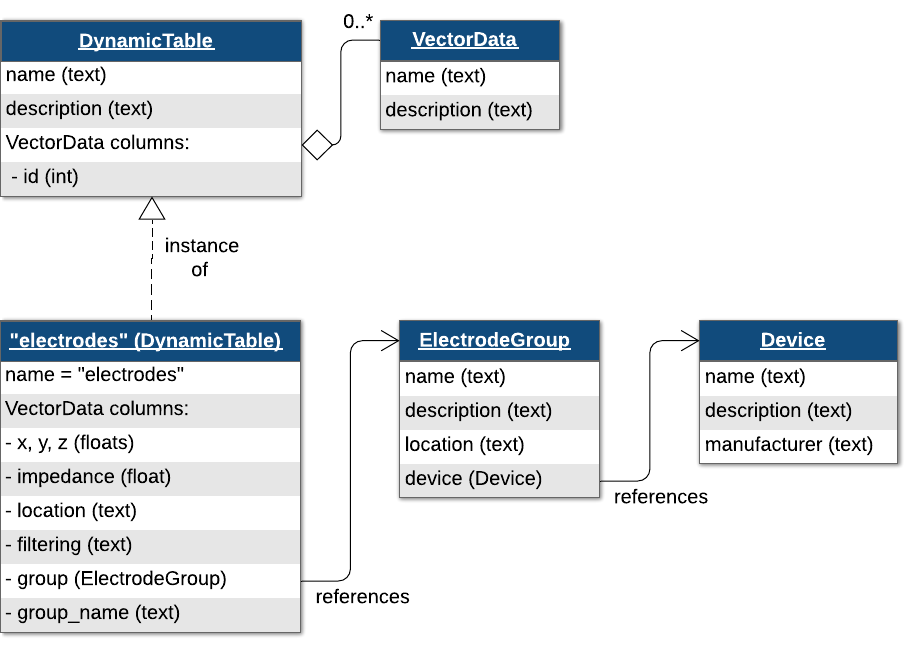

Since this is a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html), we can add additional metadata fields. We will be adding a "label" column to the table.

numShanks = 4;
numChannelsPerShank = 3;
numChannels = numShanks * numChannelsPerShank;

electrodesDynamicTable = types.hdmf_common.DynamicTable(...
    'colnames', {'location', 'group', 'group_name', 'label'}, ...
    'description', 'all electrodes');

device = types.core.Device(...
    'description', 'the best array', ...
    'manufacturer', 'Probe Company 9000' ...
);
nwb.general_devices.set('array', device);
for iShank = 1:numShanks
    shankGroupName = sprintf('shank%d', iShank);
    electrodeGroup = types.core.ElectrodeGroup( ...
        'description', sprintf('electrode group for %s', shankGroupName), ...
        'location', 'brain area', ...
        'device', types.untyped.SoftLink(device) ...
    );
    
    nwb.general_extracellular_ephys.set(shankGroupName, electrodeGroup);
    for iElectrode = 1:numChannelsPerShank
        electrodesDynamicTable.addRow( ...
            'location', 'unknown', ...
            'group', types.untyped.ObjectView(electrodeGroup), ...
            'group_name', shankGroupName, ...
            'label', sprintf('%s-electrode%d', shankGroupName, iElectrode));
    end
end
electrodesDynamicTable.toTable() % Display the table
nwb.general_extracellular_ephys_electrodes = electrodesDynamicTable;

### Links

In the above loop, we create [`ElectrodeGroup`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectrodeGroup.html) objects. The `electrodes` table then uses an `ObjectView` in each row to link to the corresponding [`ElectrodeGroup`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectrodeGroup.html) object. An `ObjectView` is a construct that enables linking one neurodata type to another, allowing a neurodata type to reference another within the NWB file.

## Recorded Extracellular Signals

Voltage data are stored using the [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) class, a subclass of the [`TimeSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TimeSeries.html) class specialized for voltage data. 

### Referencing Electrodes

In order to create our [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) object, we first need to reference a set of rows in the `electrodes` table to indicate which electrode (channel) each entry in the electrical series were recorded from. We will do this by creating a [`DynamicTableRegion`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTableRegion.html), which is a type of link that allows you to reference specific rows of a [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html), such as the `electrodes` table, using row indices.

Create a [`DynamicTableRegion`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTableRegion.html) that references all rows of the `electrodes` table.

electrode_table_region = types.hdmf_common.DynamicTableRegion( ...
    'table', types.untyped.ObjectView(electrodesDynamicTable), ...
    'description', 'all electrodes', ...
    'data', (0:length(electrodesDynamicTable.id.data)-1)');

### Raw Voltage Data

Now create an `ElectricalSeries` object to hold acquisition data collected during the experiment.

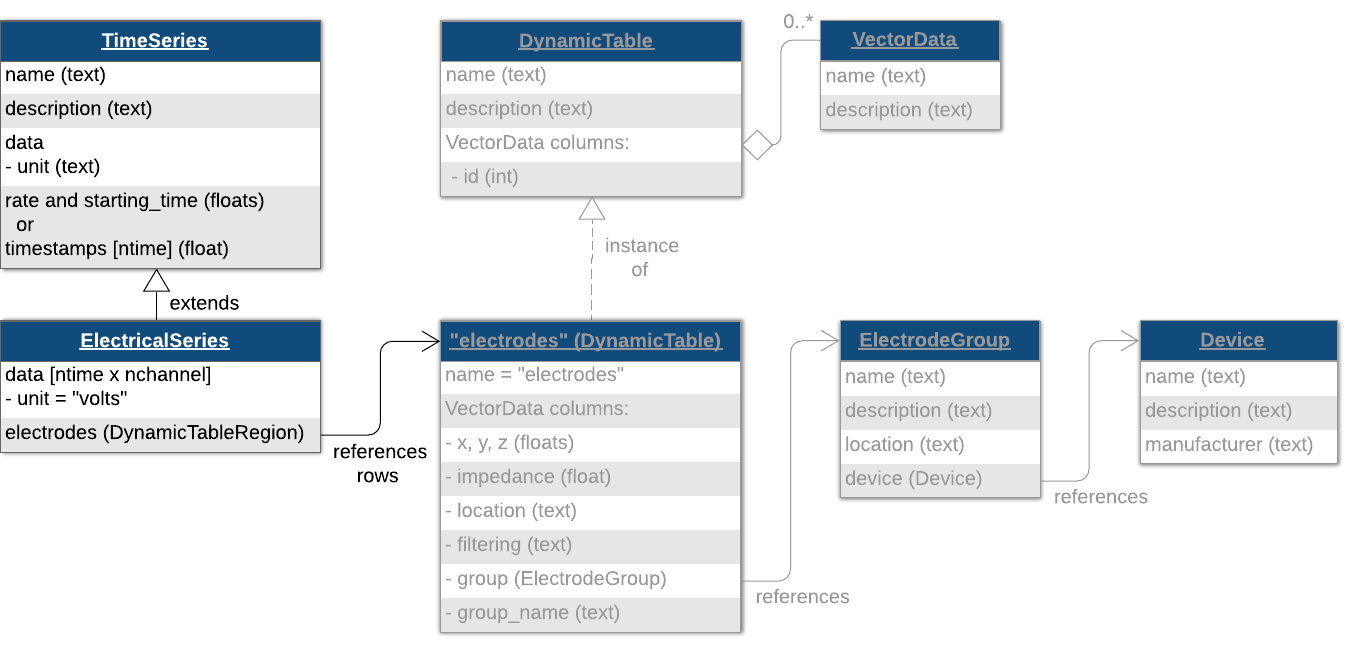

raw_electrical_series = types.core.ElectricalSeries( ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 30000., ... % Hz
    'data', randn(numChannels, 3000), ... % nChannels x nTime
    'electrodes', electrode_table_region, ...
    'data_unit', 'volts');

This is the voltage data recorded directly from our electrodes, so it goes in the acquisition group.

nwb.acquisition.set('ElectricalSeries', raw_electrical_series);

## Processed Extracellular Electrical Signals

### LFP

LFP refers to data that has been low-pass filtered, typically below 300 Hz. This data may also be downsampled. Because it is filtered and potentially resampled, it is categorized as processed data. LFP data would also be stored in an [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html). To help data analysis and visualization tools know that this [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) object represents LFP data, we store it inside an [`LFP`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/LFP.html) object and then place the [`LFP`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/LFP.html) object in a [`ProcessingModule`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ProcessingModule.html) named `'ecephys'`. This is analogous to how we stored the [`SpatialSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SpatialSeries.html) object inside of a [`Position`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Position.html) object and stored the [`Position`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Position.html) object in a [`ProcessingModule`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ProcessingModule.html) named `'behavior'` in the [behavior](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/behavior.html) tutorial

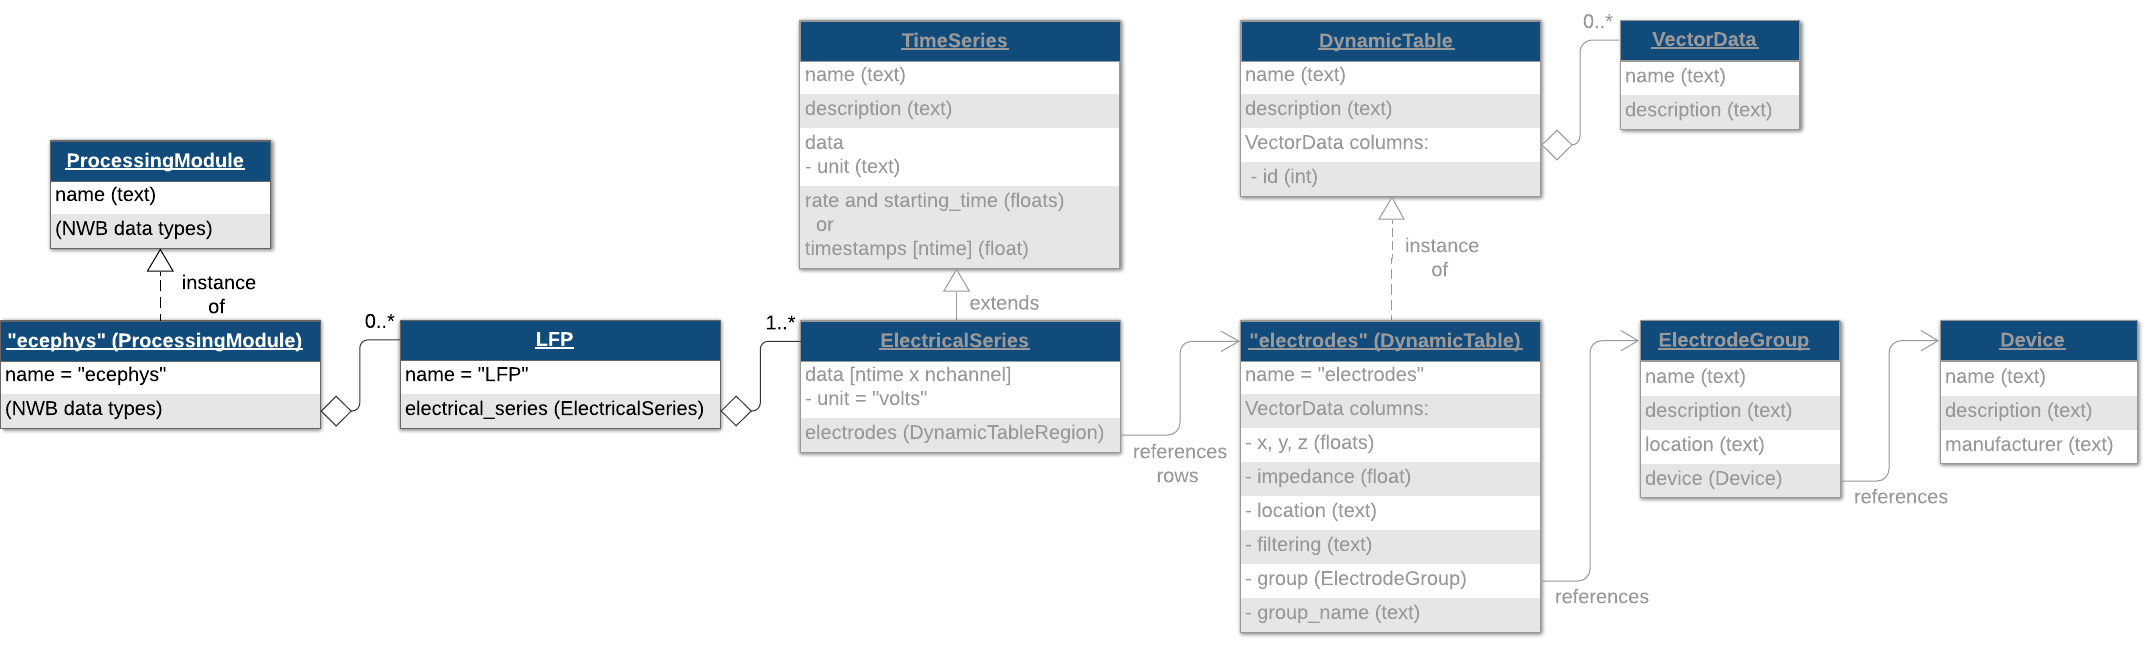

lfp_electrical_series = types.core.ElectricalSeries( ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 1000., ... % Hz
    'data', randn(numChannels, 100), ... nChannels x nTime
    'filtering', 'Low-pass filter at 300 Hz', ...
    'electrodes', electrode_table_region, ...
    'data_unit', 'volts');

lfp = types.core.LFP('ElectricalSeries', lfp_electrical_series);

ecephys_module = types.core.ProcessingModule(...
    'description', 'extracellular electrophysiology');

ecephys_module.nwbdatainterface.set('LFP', lfp);
nwb.processing.set('ecephys', ecephys_module);

### Other Types of Filtered Electrical Signals

### Decomposition of LFP Data into Frequency Bands

In some cases, you may want to further process the LFP data and decompose the signal into different frequency bands for additional downstream analyses. You can store the processed data from these spectral analyses using a [`DecompositionSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/DecompositionSeries.html) object. This object allows you to include metadata about the frequency bands and metric used (e.g., `power`, `phase`, `amplitude`), as well as link the decomposed data to the original [`TimeSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/TimeSeries.html) signal the data was derived from.

**Note**: When adding data to a [`DecompositionSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/DecompositionSeries.html), the `data` argument is assumed to be 3D where the first dimension is time, the second dimension is channels, and the third dimension is bands. In MatNWB, the data needs to be permuted because the dimensions are written to file in reverse order (See the [dimensionMapNoDataPipes](matlab:open('./dimensionMapNoDataPipes.mlx')) tutorial)

% Define the frequency bands of interest (in Hz):
band_names = {'theta'; 'beta'; 'gamma'};
band_mean = [8; 21; 55];
band_stdev = [2; 4.5; 12.5];
band_limits = [band_mean - 2*band_stdev, band_mean + 2*band_stdev];

% The bands should be added to the DecompositionSeries as a dynamic table
bands = table(band_names, band_mean, band_stdev, band_limits, ...
    'VariableNames', {'band_names', 'band_mean', 'band_stdev', 'band_limits'})

bands = util.table2nwb( bands );

% Generate random phase data for the demonstration.
phase_data = randn(50, 12, numel(band_names)); % 50 samples, 12 channels, 3 frequency bands
phase_data = permute(phase_data, [3,2,1]); % See dimensionMapNoDataPipes tutorial

decomp_series = types.core.DecompositionSeries(...
    'data', phase_data, ...
    'bands', bands, ...
    'metric', 'phase', ...
    'starting_time', 0.0, ... % seconds
    'starting_time_rate', 1000.0, ... % Hz
    'source_channels', electrode_table_region, ...
    'source_timeseries', lfp_electrical_series);

% Add decomposition series to ecephys module
ecephys_module.nwbdatainterface.set('theta', decomp_series);

## Spike Times and Extracellular Events

### Sorted Spike Times

Spike times are stored in a [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table, a specialization of the [`DynamicTable`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/DynamicTable.html) class. The default [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table is located at `/units` in the HDF5 file. You can add columns to the [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table just like you did for `electrodes` and `trials` (see [convertTrials](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/convertTrials.html)). Here, we generate some random spike data and populate the table. 

num_cells = 10;
spikes = cell(1, num_cells);
for iShank = 1:num_cells
    spikes{iShank} = rand(1, randi([16, 28]));
end
spikes

#### Ragged Arrays

Spike times are an example of a ragged array- it's like a matrix, but each row has a different number of elements. We can represent this type of data as an indexed column of the [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table. These indexed columns have two components, the [**VectorData**](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/VectorData.html) object that holds the data and the [**VectorIndex**](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+hdmf_common/VectorIndex.html) object that holds the indices in the vector that indicate the row breaks. You can use the convenience function `util.create_indexed_column` to create these objects. For more information about ragged arrays, we refer you to the **"Ragged Array Columns"** section of the [dynamic table](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/dynamic_tables.html) tutorial.

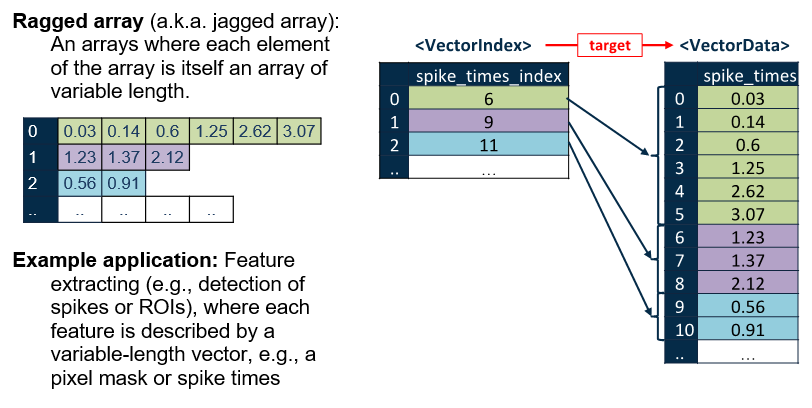

[spike_times_vector, spike_times_index] = util.create_indexed_column(spikes);

nwb.units = types.core.Units( ...
    'colnames', {'spike_times'}, ...
    'description', 'units table', ...
    'spike_times', spike_times_vector, ...
    'spike_times_index', spike_times_index ...
);

nwb.units.toTable

### Unsorted Spike Times

While the [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table is used to store spike times and waveform data for spike-sorted, single-unit activity, you may also want to store spike times and waveform snippets of unsorted spiking activity. This is useful for recording multi-unit activity detected via threshold crossings during data acquisition. Such information can be stored using [`SpikeEventSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SpikeEventSeries.html) objects.

% In the SpikeEventSeries the dimensions should be ordered as 
% [num_events, num_channels, num_samples].
% Define spike snippets: 20 events, 3 channels, 40 samples per event. 
spike_snippets = rand(20, 3, 40);
% Permute spike snippets (See dimensionMapNoDataPipes tutorial)
spike_snippets = permute(spike_snippets, [3,2,1]) 

% Create electrode table region referencing electrodes 0, 1, and 2
shank0_table_region = types.hdmf_common.DynamicTableRegion( ...
    'table', types.untyped.ObjectView(electrodesDynamicTable), ...
    'description', 'shank0', ...
    'data', (0:2)');

% Define spike event series for unsorted spike times
spike_events = types.core.SpikeEventSeries( ...
    'data', spike_snippets, ...
    'timestamps', (0:19)', ...  % Timestamps for each event
    'description', 'events detected with 100uV threshold', ...
    'electrodes', shank0_table_region ...
);

% Add spike event series to NWB file acquisition
nwb.acquisition.set('SpikeEvents_Shank0', spike_events);

### Detected Events

If you need to store the complete, continuous raw voltage traces, along with unsorted spike times, you should store the traces in [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects in the acquisition group, and use the [`EventDetection`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/EventDetection.html) class to identify the spike events in your raw traces.

% Create the EventDetection object
event_detection = types.core.EventDetection( ...
    'detection_method', 'thresholding, 1.5 * std', ...
    'source_electricalseries', types.untyped.SoftLink(raw_electrical_series), ...
    'source_idx', [1000; 2000; 3000], ...
    'times', [.033, .066, .099] ...
);

% Add the EventDetection object to the ecephys module
ecephys_module.nwbdatainterface.set('ThresholdEvents', event_detection);

### Storing Spike Features (e.g Principal Components)

NWB also provides a way to store features of spikes, such as principal components, using the [`FeatureExtraction`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/FeatureExtraction.html) class. 

% Generate random feature data (time x channel x feature)
features = rand(3, 12, 4); % 3 time points, 12 channels, 4 features
features = permute(features, [3,2,1]) % reverse dimension order for matnwb

% Create the FeatureExtraction object
feature_extraction = types.core.FeatureExtraction( ...
    'description', {'PC1', 'PC2', 'PC3', 'PC4'}, ... % Feature descriptions
    'electrodes', electrode_table_region, ... % DynamicTableRegion referencing the electrodes table
    'times', [.033; .066; .099], ... % Column vector for times
    'features', features ...
);

% Add the FeatureExtraction object to the ecephys module (if required)
ecephys_module.nwbdatainterface.set('PCA_features', feature_extraction);

## Choosing NWB-Types for Electrophysiology Data (A Summary)

As mentioned above, [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects are meant for storing electrical timeseries data like raw voltage signals or processed signals like LFP or other filtered signals. In addition to the [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) class, NWB provides some more classes for storing event-based electropysiological data. We will briefly discuss them here, and refer the reader to the [**API documentation**](https://neurodatawithoutborders.github.io/matnwb/doc/index.html) and the section on [Extracellular Physiology](https://nwb-schema.readthedocs.io/en/latest/format.html#extracellular-electrophysiology) in the "NWB Format Specification" for more details on using these objects.

For storing unsorted spiking data, there are two options. Which one you choose depends on what data you have available. If you need to store complete and/or continuous raw voltage traces, you should store the traces with [`ElectricalSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/ElectricalSeries.html) objects as acquisition data, and use the [`EventDetection`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/EventDetection.html) class for identifying the spike events in your raw traces. If you do not want to store the entire raw voltage traces, only the waveform ‘snippets’ surrounding spike events, you should use [`SpikeEventSeries`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/SpikeEventSeries.html) objects.

The results of spike sorting (or clustering) should be stored in the top-level [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table. The [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table can hold just the spike times of sorted units or, optionally, include additional waveform information. You can use the optional predefined columns `waveform_mean`, `waveform_sd`, and `waveforms` in the [`Units`](https://neurodatawithoutborders.github.io/matnwb/doc/+types/+core/Units.html) table to store individual and mean waveform data.

## Writing the NWB File

nwbExport(nwb, 'ecephys_tutorial.nwb')

## Reading NWB Data

Data arrays are read passively from the file. Calling `TimeSeries.data` does not read the data values, but presents an HDF5 object that can be indexed to read data. This allows you to conveniently work with datasets that are too large to fit in RAM all at once. `load` with no input arguments reads the entire dataset:

nwb2 = nwbRead('ecephys_tutorial.nwb', 'ignorecache');
nwb2.processing.get('ecephys'). ...
    nwbdatainterface.get('LFP'). ...
    electricalseries.get('ElectricalSeries'). ...
    data.load;

## Accessing Data Regions

If all you need is a data region, you can index a `DataStub` object like you would any normal array in MATLAB, as shown below. When indexing the dataset this way, only the selected region is read from disk into RAM. This allows you to handle very large datasets that would not fit entirely into RAM.

% read section of LFP
nwb2.processing.get('ecephys'). ...
    nwbdatainterface.get('LFP'). ...
    electricalseries.get('ElectricalSeries'). ...
    data(1:5, 1:10)

% You can use the getRow method of the table to load spike times of a specific unit.
% To get the values, unpack from the returned table.
nwb.units.getRow(1).spike_times{1}

# Learn more!

### See the [API documentation](https://neurodatawithoutborders.github.io/matnwb/doc/index.html) to learn what data types are available.

## MATLAB tutorials

- [Optical physiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/ophys.html)

- [Intracellular electrophysiology](https://neurodatawithoutborders.github.io/matnwb/tutorials/html/icephys.html)

## Python tutorials

See our tutorials for more details about your data type:

- [Calcium imaging](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ophys.html#sphx-glr-tutorials-domain-ophys-py)

- [Extracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/ecephys.html#sphx-glr-tutorials-domain-ecephys-py)

- [Intracellular electrophysiology](https://pynwb.readthedocs.io/en/stable/tutorials/domain/icephys.html#sphx-glr-tutorials-domain-icephys-py)

**Check out other tutorials that teach advanced NWB topics:**

- [Iterative data write](https://pynwb.readthedocs.io/en/stable/tutorials/general/iterative_write.html#sphx-glr-tutorials-general-iterative-write-py)

- [Extensions](https://pynwb.readthedocs.io/en/stable/tutorials/general/extensions.html#sphx-glr-tutorials-general-extensions-py)

- [Advanced HDF5 I/O](https://pynwb.readthedocs.io/en/stable/tutorials/general/advanced_hdf5_io.html#sphx-glr-tutorials-general-advanced-hdf5-io-py)